clear; close all;

global SMOOTH_ON;
SMOOTH_ON = true;

function y = EaseCube(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        if t(i) < 0.5
            y(i) = 4*t(i)^3;
        else
            y(i) = 0.5*(2*t(i)-2)^3 + 1;
        end
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

function y = EaseSine(t, start_deg, end_deg)
    len = length(t);
    for i = 1:len
        y(i) = -0.5 * cos(pi*t(i)) + 0.5;
    end
    y = y.*(end_deg - start_deg) + start_deg;
end

function y = smooth(x, K)
    pre = 15;
    post = 15;
    global SMOOTH_ON
    if SMOOTH_ON
        temp = smoothdata([x(end-(pre-1):end), x, x(1:post)], 'sgolay', K);
        y = temp(pre+1:end-post);
    else
        y = x;
    end
end

N = 24;
K=2;    % time_long / time_short ratio
T = 6;

time_long = linspace(0,1, N * K/(K + 1) )

time_long =          0    0.0667    0.1333    0.2000    0.2667    0.3333    0.4000    0.4667    0.5333    0.6000    0.6667    0.7333    0.8000    0.8667    0.9333    1.0000


time_short = linspace(0,1,N * 1/(K + 1) )

time_short =          0    0.1429    0.2857    0.4286    0.5714    0.7143    0.8571    1.0000


time_up = linspace(0,1,length(time_short)/2 + T)

time_up =          0    0.1111    0.2222    0.3333    0.4444    0.5556    0.6667    0.7778    0.8889    1.0000


time_floor = length(time_long) - 2*T

time_floor = 4


start_deg = [68 112  82 98 90  90  90 90];
end_deg =   [98  82 112 68 75 105 105 75];
shift = [0 N*0.5 N*0.75 N*0.25];


Leg_0 = [EaseSine(time_long, start_deg(1), end_deg(1)) EaseSine(time_short, end_deg(1), start_deg(1))]

Leg_0 =    68.0000   68.3278   69.2968   70.8647   72.9630   75.5000   78.3647   81.4321   84.5679   87.6353   90.5000   93.0370   95.1353   96.7032   97.6722   98.0000   98.0000   96.5145   92.3523   86.3378   79.6622   73.6477   69.4855   68.0000


Leg_1 = circshift([EaseSine(time_long, start_deg(2), end_deg(2)) EaseSine(time_short, end_deg(2), start_deg(2))], shift(2))

Leg_1 =    84.8647   83.2968   82.3278   82.0000   82.0000   83.4855   87.6477   93.6622  100.3378  106.3523  110.5145  112.0000  112.0000  111.6722  110.7032  109.1353  107.0370  104.5000  101.6353   98.5679   95.4321   92.3647   89.5000   86.9630


Leg_2 = circshift([EaseSine(time_long, start_deg(3), end_deg(3)) EaseSine(time_short, end_deg(3), start_deg(3))], shift(3))

Leg_2 =    92.3647   95.4321   98.5679  101.6353  104.5000  107.0370  109.1353  110.7032  111.6722  112.0000  112.0000  110.5145  106.3523  100.3378   93.6622   87.6477   83.4855   82.0000   82.0000   82.3278   83.2968   84.8647   86.9630   89.5000


Leg_3 = circshift([EaseSine(time_long, start_deg(4), end_deg(4)) EaseSine(time_short, end_deg(4), start_deg(4))], shift(4))

Leg_3 =    73.6477   79.6622   86.3378   92.3523   96.5145   98.0000   98.0000   97.6722   96.7032   95.1353   93.0370   90.5000   87.6353   84.5679   81.4321   78.3647   75.5000   72.9630   70.8647   69.2968   68.3278   68.0000   68.0000   69.4855



Leg_4 = circshift([linspace(start_deg(5), start_deg(5), time_floor) EaseSine(time_up, start_deg(5), end_deg(5)) EaseSine(time_up, end_deg(5), start_deg(5))], T+0)

Leg_4 =    81.1976   83.8024   86.2500   88.2453   89.5477   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   89.5477   88.2453   86.2500   83.8024   81.1976   78.7500   76.7547   75.4523   75.0000   75.0000   75.4523   76.7547   78.7500


Leg_5 = circshift([linspace(start_deg(6), start_deg(6), time_floor) EaseSine(time_up, start_deg(6), end_deg(6)) EaseSine(time_up, end_deg(6), start_deg(6))], T+shift(2))

Leg_5 =    91.7547   93.7500   96.1976   98.8024  101.2500  103.2453  104.5477  105.0000  105.0000  104.5477  103.2453  101.2500   98.8024   96.1976   93.7500   91.7547   90.4523   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   90.4523


Leg_6 = circshift([linspace(start_deg(7), start_deg(7), time_floor) EaseSine(time_up, start_deg(7), end_deg(7)) EaseSine(time_up, end_deg(7), start_deg(7))], T+shift(3))

Leg_6 =    90.0000   90.0000   90.0000   90.0000   90.0000   90.4523   91.7547   93.7500   96.1976   98.8024  101.2500  103.2453  104.5477  105.0000  105.0000  104.5477  103.2453  101.2500   98.8024   96.1976   93.7500   91.7547   90.4523   90.0000


Leg_7 = circshift([linspace(start_deg(8), start_deg(8), time_floor) EaseSine(time_up, start_deg(8), end_deg(8)) EaseSine(time_up, end_deg(8), start_deg(8))], T+shift(4))

Leg_7 =    75.4523   75.0000   75.0000   75.4523   76.7547   78.7500   81.1976   83.8024   86.2500   88.2453   89.5477   90.0000   90.0000   90.0000   90.0000   90.0000   90.0000   89.5477   88.2453   86.2500   83.8024   81.1976   78.7500   76.7547


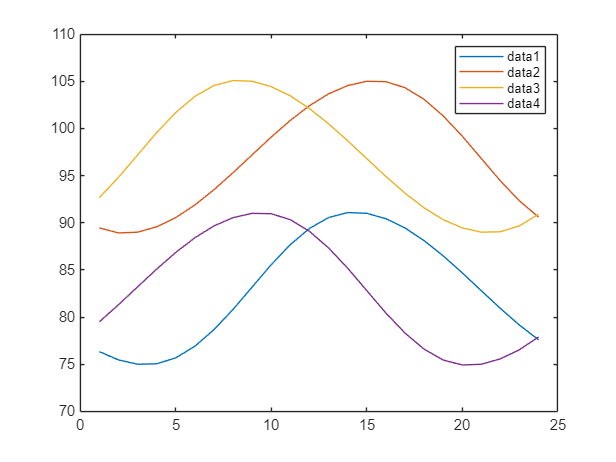


Leg_0 = smooth(Leg_0, 30);
Leg_1 = smooth(Leg_1, 30);
Leg_2 = smooth(Leg_2, 30);
Leg_3 = smooth(Leg_3, 30);

plot(linspace(1,N,N), Leg_0); hold on;
plot(linspace(1,N,N), Leg_1);
plot(linspace(1,N,N), Leg_2);
plot(linspace(1,N,N), Leg_3);
hold off;
legend;

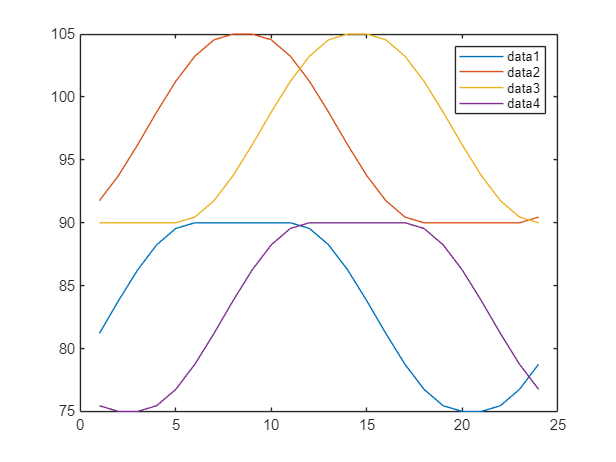


plot([linspace(1,N,N)], Leg_4); hold on;
plot([linspace(1,N,N)], Leg_5);
plot([linspace(1,N,N)], Leg_6);
plot([linspace(1,N,N)], Leg_7);
hold off;
legend;

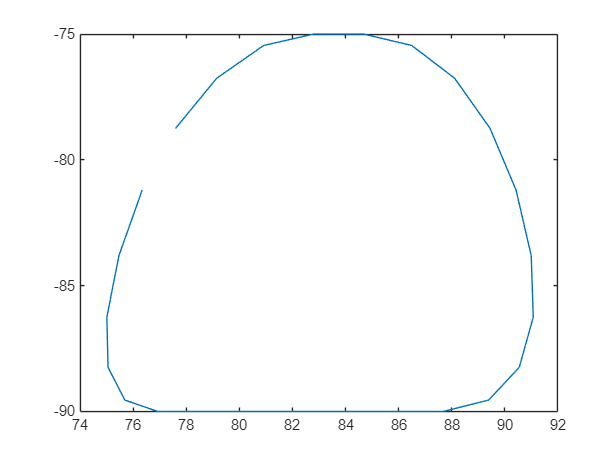


plot(Leg_0, -Leg_4); hold on;
hold off;


% Post-procces commmands
R = 2;
Leg_0 = round(Leg_0, R);
Leg_1 = round(Leg_1, R);
Leg_2 = round(Leg_2, R);
Leg_3 = round(Leg_3, R);
Leg_4 = round(Leg_4, R);
Leg_5 = round(Leg_5, R);
Leg_6 = round(Leg_6, R);
Leg_7 = round(Leg_7, R);


% Create commands
loop_time = 1008;
for i = 1:N
    if i == 1
        fprintf('V1\nE0\nM: %g, %g, %g, %g, %g, %g, %g, %g\nV10\nW100\n----------\n', Leg_0(1), Leg_1(1), Leg_2(1), Leg_3(1), Leg_4(1), Leg_5(1), Leg_6(1), Leg_7(1))
    end
    fprintf('M: %g, %g, %g, %g, %g, %g, %g, %g\n', Leg_0(i), Leg_1(i), Leg_2(i), Leg_3(i), Leg_4(i), Leg_5(i), Leg_6(i), Leg_7(i));
end

V1
E0
M: 76.33, 89.45, 92.67, 79.5, 81.2, 91.75, 90, 75.45
V10
W100
----------


M: 76.33, 89.45, 92.67, 79.5, 81.2, 91.75, 90, 75.45
M: 75.46, 88.92, 94.82, 81.31, 83.8, 93.75, 90, 75
M: 75, 89, 97.19, 83.21, 86.25, 96.2, 90, 75
M: 75.04, 89.57, 99.56, 85.09, 88.25, 98.8, 90, 75.45
M: 75.68, 90.55, 101.69, 86.86, 89.55, 101.25, 90, 76.75
M: 76.91, 91.89, 103.4, 88.41, 90, 103.25, 90.45, 78.75
M: 78.67, 93.5, 104.55, 89.67, 90, 104.55, 91.75, 81.2
M: 80.82, 95.31, 105.08, 90.54, 90, 105, 93.75, 83.8
M: 83.19, 97.21, 105, 91, 90, 105, 96.2, 86.25
M: 85.56, 99.09, 104.43, 90.96, 90, 104.55, 98.8, 88.25
M: 87.69, 100.86, 103.45, 90.32, 90, 103.25, 101.25, 89.55
M: 89.4, 102.41, 102.11, 89.09, 89.55, 101.25, 103.25, 90
M: 90.55, 103.67, 100.5, 87.33, 88.25, 98.8, 104.55, 90
M: 91.08, 104.54, 98.69, 85.18, 86.25, 96.2, 105, 90
M: 91, 105, 96.79, 82.81, 83.8, 93.75, 105, 90
M: 90.43, 104.96, 94.91, 80.44, 81.2, 91.75, 104.55, 90
M: 89.45, 104.32, 93.14, 78.31, 78.75, 90.45, 103.25, 90
M: 88.11, 103.09, 91.59, 76.6, 76.75, 90, 101.25, 89.55
M: 86.5, 101.33, 90.33, 75.45, 